% calculate and plot state value

Animal = {'tph209','tph210','tph218','tph227','tph228'}; %'s19';  'tph209', 'tph199'
Date = {'20230829','20230818','20230818','20230818','20230818'}; % '20230819' '20230602' '20230827'
totalTrial = 150;
Key = {'uniformh','uniformh','uniformh','uniformh','uniformh'}; % 'heavy90''roving25s'
gamma = 0.9; % discount factor
position_range = [657 672]; % [630-647]
force_dividing_factor = 12.5; % 0.1
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
% load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
% data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation'  filesep Date '_' Animal '_' Key]; % Linux
% load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
% data = behavior_sequence_fps;
output_dir = '/home/naohiro/Desktop/Doya_rotation/analysis/output/behavior/231111/';

data_folders = cell(1,length(Animal));
% data_folders = [];
data = cell(length(Animal),totalTrial);
for i = 1:length(Animal)
    data_folders(i) = {['/media/naohiro/ADATA HV620S/Doya_rotation/202308' filesep strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))]}; % /202308
    load([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat']);
    data(i,:) = behavior_sequence_fps;
end

% bin the state and action to calculate state value and action value
behavior_sequence_discretized = cell(size(data));
for j_animal = 1:length(Animal)
    for i_trial = 1:totalTrial
        % bin lever position (657-672 -> 5-1) % bin lever position (630-647 -> 6-1)
        position_temp = data{j_animal,i_trial}(:,3);
        position_discrete = 6 - min(max(floor((position_temp - (position_range(1)-6))/4),1),5);
    %     position_discrete = 7 - min(max(floor((position_temp - 623)/4),1),6);
    %     position_discrete = zeros(length(position_temp));
    %     for j_time = 1:length(position_temp)
    %         if position_temp(j_time) <= 
        % bin applied force (0-0.7 -> 0-7)
        force_temp = data{j_animal,i_trial}(:,4);
        force_discrete = min(max(floor(force_temp/force_dividing_factor),0),7);
    %     force_discrete = min(max(idivide(force_temp,0.1,'floor'),0),7);
        behavior_sequence_discretized{j_animal,i_trial} = cat(2,cat(2,data{j_animal,i_trial},position_discrete),force_discrete);
    end
end

% analyze first 50 of last 50 trials as before and after adaptation
behavior_adapt = cell(length(Animal),3,50);
for j_animal = 1:length(Animal)
    behavior_adapt(j_animal,1,:) = behavior_sequence_discretized(j_animal,1:50); % first 50 behavior_before_adapt
    behavior_adapt(j_animal,2,:) = behavior_sequence_discretized(j_animal,51:100); % behavior_after_adapt
    behavior_adapt(j_animal,3,:) = behavior_sequence_discretized(j_animal,101:150); % behavior_after_adapt
end

% calculate state value for each discretized state
% 2 (resistance) * 5 (position) = 10 states % 2 (resistance) * 6 (position) = 12 states
state_value = cell(length(Animal),3,10);
for j_animal = 1:length(Animal)
    for k = 1:3
        for i_trial = 1:50
            % resistance for each trial
            if behavior_adapt{j_animal,k,i_trial}(1,2) == 8
                resistance_trial = 1;
            else 
                resistance_trial = 2;
            end
            % rewarded step (end of trial) or not (0)
            if max(behavior_adapt{j_animal,k,i_trial}(:,5)) == 1
                rewarded_trial = length(behavior_adapt{j_animal,k,i_trial});
            else 
                rewarded_trial = 0;
            end
            % add state_value of each step
            for j_step = 1:size(behavior_adapt{j_animal,k,i_trial},1)
                state_temp = (resistance_trial-1)*5+behavior_adapt{j_animal,k,i_trial}(j_step,7);
                if rewarded_trial >= 1
                    state_value_temp = gamma.^(rewarded_trial-j_step);
                else
                    state_value_temp = 0;
                end
                state_value{j_animal,k,state_temp} = [state_value{j_animal,k,state_temp} state_value_temp];
            end
        end
    end
end

state_value_average = zeros(length(Animal),3,10);
for j_animal = 1:length(Animal)
    for i = 1:10
        state_value_average(j_animal,1,i) = mean(state_value{j_animal,1,i});
        state_value_average(j_animal,2,i) = mean(state_value{j_animal,2,i});
        state_value_average(j_animal,3,i) = mean(state_value{j_animal,3,i});
    end
end

% temp_state_value_average = zeros(length(Animal),3,10);
% for j_animal = 1:length(Animal)
%     for i = 1:10
%         temp_state_value_average(j_animal,1,i) = mean(state_value{j_animal,1,i});
%         temp_state_value_average(j_animal,2,i) = mean(state_value{j_animal,2,i});
%         temp_state_value_average(j_animal,3,i) = mean(state_value{j_animal,3,i});
%     end
% end
% state_value_average = squeeze(nanmean(temp_state_value_average,1));

% calculate action value for each discretized state and action
action_value = cell(length(Animal),3,10,8);
for j_animal = 1:length(Animal)
    for k = 1:3
        for i_trial = 1:50
            % resistance for each trial
            if behavior_adapt{j_animal,k,i_trial}(1,2) == 8
                resistance_trial = 1;
            else 
                resistance_trial = 2;
            end
            % rewarded step (end of trial) or not (0)
            if max(behavior_adapt{j_animal,k,i_trial}(:,5)) == 1
                rewarded_trial = length(behavior_adapt{j_animal,k,i_trial});
            else 
                rewarded_trial = 0;
            end
            % add state_value of each step
            for j_step = 1:size(behavior_adapt{j_animal,k,i_trial},1)-1
                state_temp = (resistance_trial-1)*5+behavior_adapt{j_animal,k,i_trial}(j_step,7);
                state_temp_forward = (resistance_trial-1)*5+behavior_adapt{j_animal,k,i_trial}(j_step+1,7);
                action_temp = behavior_adapt{j_animal,k,i_trial}(j_step,8)+1;
                state_value_average_temp = state_value_average(j_animal,k,state_temp_forward);
                if rewarded_trial == j_step+1
                    action_value_temp = 1; % + gamma*state_value_average_temp;
                else
                    action_value_temp = gamma*state_value_average_temp;
                end
                action_value{j_animal,k,state_temp,action_temp} = [action_value{j_animal,k,state_temp,action_temp} action_value_temp];
            end
        end
    end
end

temp_action_value_average = zeros(length(Animal),3,10,8);
for j_animal = 1:length(Animal)
    for i = 1:10
        for j = 1:8
            temp_action_value_average(j_animal,1,i,j) = mean(action_value{j_animal,1,i,j});
            temp_action_value_average(j_animal,2,i,j) = mean(action_value{j_animal,2,i,j});
            temp_action_value_average(j_animal,3,i,j) = mean(action_value{j_animal,3,i,j});        
        end
    end
end
action_value_average = squeeze(nanmean(temp_action_value_average,1));

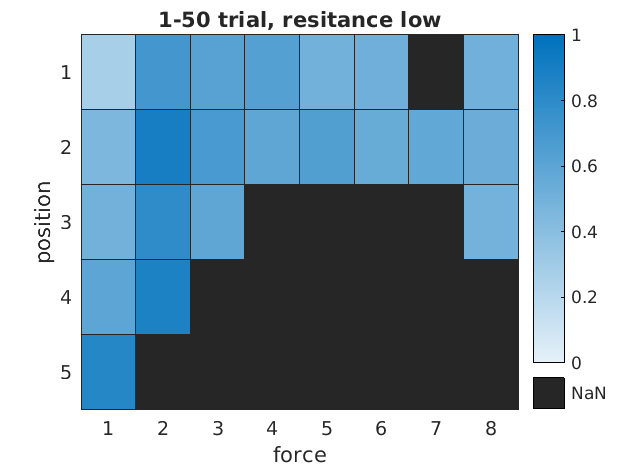

% plot action value
action_value_average_reshape1 = squeeze(action_value_average(1,1:5,:));
heatmap(action_value_average_reshape1,'ColorLimits',[0 1],'Title','1-50 trial, resitance low','XLabel','force','YLabel','position')

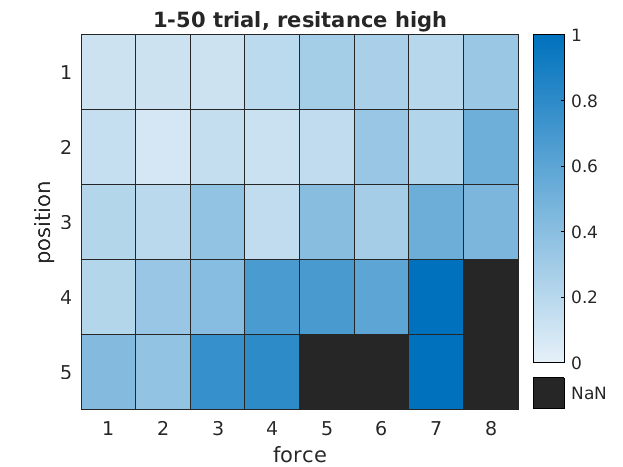

% heatmap(action_value_average_reshape1,'ColorLimits',[0 1],'Title','First half trial, resitance low','XLabel','force','YLabel','position')

action_value_average_reshape2 = squeeze(action_value_average(1,6:10,:));
heatmap(action_value_average_reshape2,'ColorLimits',[0 1],'Title','1-50 trial, resitance high','XLabel','force','YLabel','position')

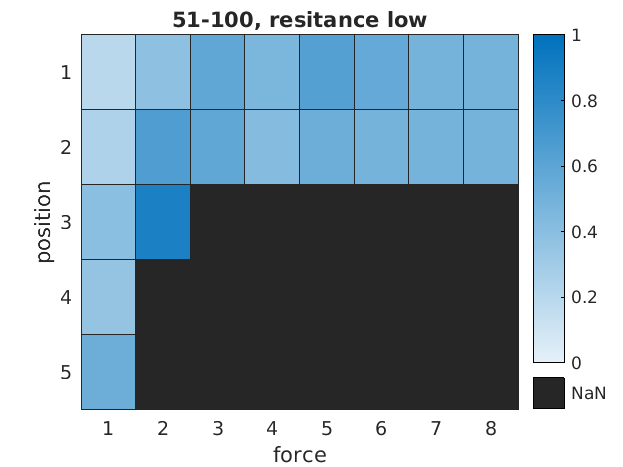

% heatmap(action_value_average_reshape2,'ColorLimits',[0 1],'Title','First half trial, resitance high','XLabel','force','YLabel','position')

action_value_average_reshape3 = squeeze(action_value_average(2,1:5,:));
heatmap(action_value_average_reshape3,'ColorLimits',[0 1],'Title','51-100, resitance low','XLabel','force','YLabel','position')

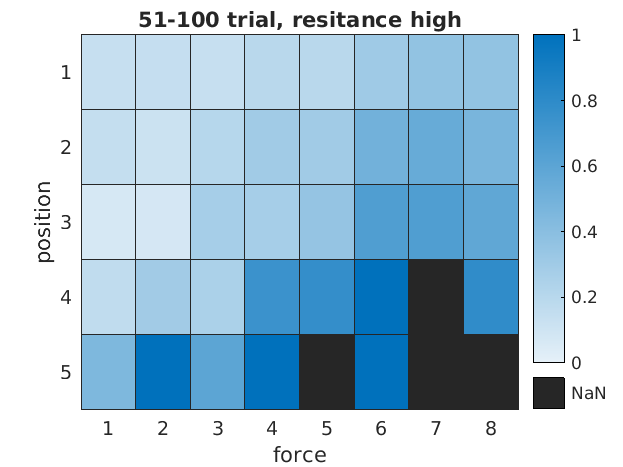

% heatmap(action_value_average_reshape3,'ColorLimits',[0 1],'Title','Second half trial, resitance low','XLabel','force','YLabel','position')

action_value_average_reshape4 = squeeze(action_value_average(2,6:10,:));
heatmap(action_value_average_reshape4,'ColorLimits',[0 1],'Title','51-100 trial, resitance high','XLabel','force','YLabel','position')

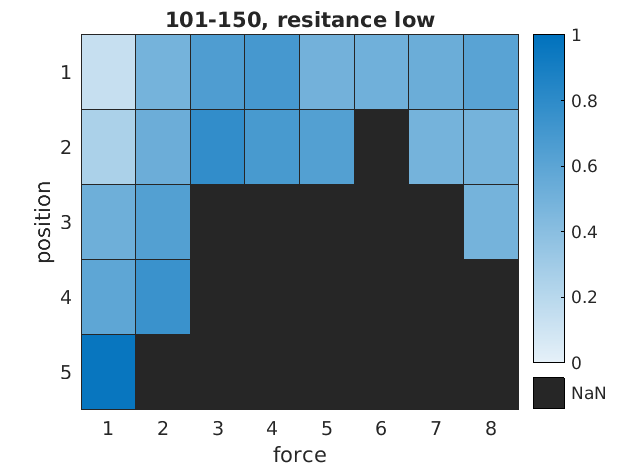

% heatmap(action_value_average_reshape4,'ColorLimits',[0 1],'Title','Second half trial, resitance high','XLabel','force','YLabel','position')

action_value_average_reshape5 = squeeze(action_value_average(3,1:5,:));
heatmap(action_value_average_reshape5,'ColorLimits',[0 1],'Title','101-150, resitance low','XLabel','force','YLabel','position')

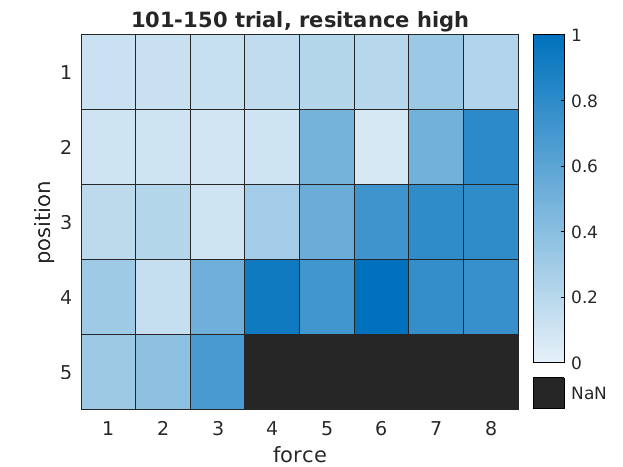

% heatmap(action_value_average_reshape3,'ColorLimits',[0 1],'Title','Second half trial, resitance low','XLabel','force','YLabel','position')

action_value_average_reshape6 = squeeze(action_value_average(3,6:10,:));
heatmap(action_value_average_reshape6,'ColorLimits',[0 1],'Title','101-150 trial, resitance high','XLabel','force','YLabel','position')

% heatmap(action_value_average_reshape4,'ColorLimits',[0 1],'Title','Second half trial, resitance high','XLabel','force','YLabel','position')

% discretize force into just 3
% calculate state value for each discretized state
% 2 (resistance) * 5 (position) = 10 states % 2 (resistance) * 6 (position) = 12 states
state_value = cell(length(Animal),3,10);
for j_animal = 1:length(Animal)
    for k = 1:3
        for i_trial = 1:50
            % resistance for each trial
            if behavior_adapt{j_animal,k,i_trial}(1,2) == 8
                resistance_trial = 1;
            else 
                resistance_trial = 2;
            end
            % rewarded step (end of trial) or not (0)
            if max(behavior_adapt{j_animal,k,i_trial}(:,5)) == 1
                rewarded_trial = length(behavior_adapt{j_animal,k,i_trial});
            else 
                rewarded_trial = 0;
            end
            % add state_value of each step
            for j_step = 1:size(behavior_adapt{j_animal,k,i_trial},1)
                state_temp = (resistance_trial-1)*5+behavior_adapt{j_animal,k,i_trial}(j_step,7);
                if rewarded_trial >= 1
                    state_value_temp = gamma.^(rewarded_trial-j_step);
                else
                    state_value_temp = 0;
                end
                state_value{j_animal,k,state_temp} = [state_value{j_animal,k,state_temp} state_value_temp];
            end
        end
    end
end

state_value_average = zeros(length(Animal),3,10);
for j_animal = 1:length(Animal)
    for i = 1:10
        state_value_average(j_animal,1,i) = mean(state_value{j_animal,1,i});
        state_value_average(j_animal,2,i) = mean(state_value{j_animal,2,i});
        state_value_average(j_animal,3,i) = mean(state_value{j_animal,3,i});
    end
end

% calculate action value for each discretized state and action
action_value = cell(length(Animal),3,10,3);
for j_animal = 1:length(Animal)
    for k = 1:3
        for i_trial = 1:50
            % resistance for each trial
            if behavior_adapt{j_animal,k,i_trial}(1,2) == 8
                resistance_trial = 1;
            else 
                resistance_trial = 2;
            end
            % rewarded step (end of trial) or not (0)
            if max(behavior_adapt{j_animal,k,i_trial}(:,5)) == 1
                rewarded_trial = length(behavior_adapt{j_animal,k,i_trial});
            else 
                rewarded_trial = 0;
            end
            % add state_value of each step
            for j_step = 1:size(behavior_adapt{j_animal,k,i_trial},1)-1
                state_temp = (resistance_trial-1)*5+behavior_adapt{j_animal,k,i_trial}(j_step,7);
                state_temp_forward = (resistance_trial-1)*5+behavior_adapt{j_animal,k,i_trial}(j_step+1,7);
                action_temp = min(behavior_adapt{j_animal,k,i_trial}(j_step,8)+1,3); % clip discretize force up to 3
                state_value_average_temp = state_value_average(j_animal,k,state_temp_forward);
                if rewarded_trial == j_step+1
                    action_value_temp = 1; % + gamma*state_value_average_temp;
                else
                    action_value_temp = gamma*state_value_average_temp;
                end
                action_value{j_animal,k,state_temp,action_temp} = [action_value{j_animal,k,state_temp,action_temp} action_value_temp];
            end
        end
    end
end

% action_value_average = zeros(3,10,3);
% for i = 1:10
%     for j = 1:3
%         action_value_average(1,i,j) = mean(action_value{1,i,j});
%         action_value_average(2,i,j) = mean(action_value{2,i,j});
%         action_value_average(3,i,j) = mean(action_value{3,i,j});        
%     end
% end

temp_action_value_average = zeros(length(Animal),3,10,3);
for j_animal = 1:length(Animal)
    for i = 1:10
        for j = 1:3
            temp_action_value_average(j_animal,1,i,j) = mean(action_value{j_animal,1,i,j});
            temp_action_value_average(j_animal,2,i,j) = mean(action_value{j_animal,2,i,j});
            temp_action_value_average(j_animal,3,i,j) = mean(action_value{j_animal,3,i,j});        
        end
    end
end
action_value_average = squeeze(nanmean(temp_action_value_average,1));

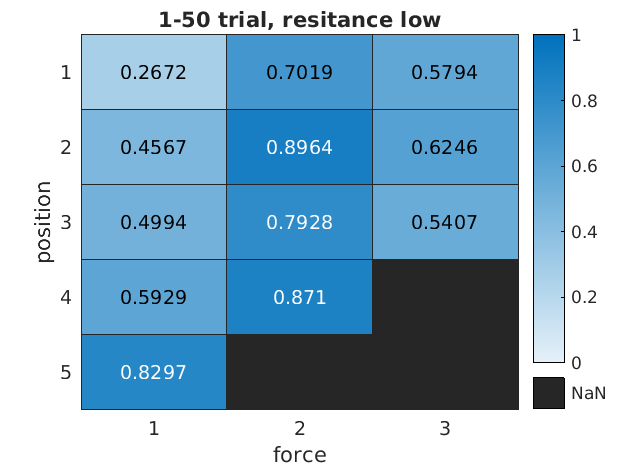

% plot action value
action_value_average_reshape1 = squeeze(action_value_average(1,1:5,:));
heatmap(action_value_average_reshape1,'ColorLimits',[0 1],'Title','1-50 trial, resitance low','XLabel','force','YLabel','position')
% heatmap(action_value_average_reshape1,'ColorLimits',[0 1],'Title','First half trial, resitance low','XLabel','force','YLabel','position')
filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_Action_Value_1-50_low.png'];
saveas(gcf,filename);

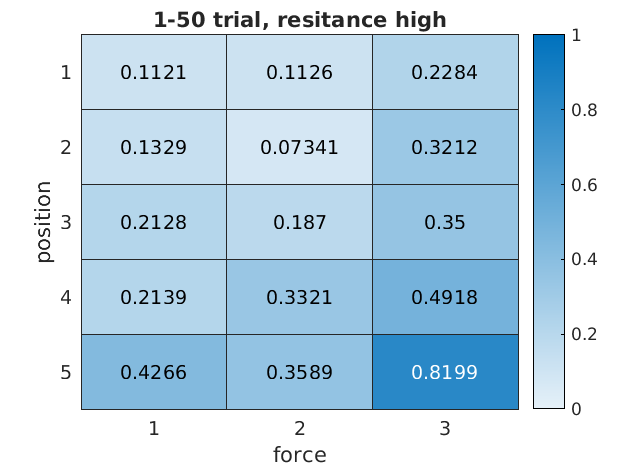


action_value_average_reshape2 = squeeze(action_value_average(1,6:10,:));
heatmap(action_value_average_reshape2,'ColorLimits',[0 1],'Title','1-50 trial, resitance high','XLabel','force','YLabel','position')
% heatmap(action_value_average_reshape2,'ColorLimits',[0 1],'Title','First half trial, resitance high','XLabel','force','YLabel','position')
filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_Action_Value_1-50_high.png'];
saveas(gcf,filename);

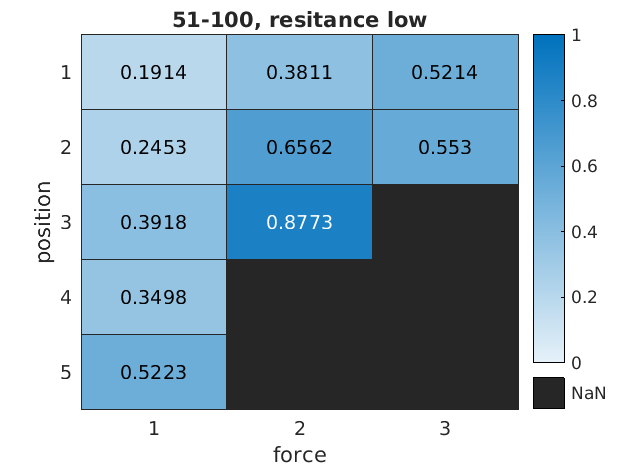


action_value_average_reshape3 = squeeze(action_value_average(2,1:5,:));
heatmap(action_value_average_reshape3,'ColorLimits',[0 1],'Title','51-100, resitance low','XLabel','force','YLabel','position')
% heatmap(action_value_average_reshape3,'ColorLimits',[0 1],'Title','Second half trial, resitance low','XLabel','force','YLabel','position')
filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_Action_Value_51-100_low.png'];
saveas(gcf,filename);

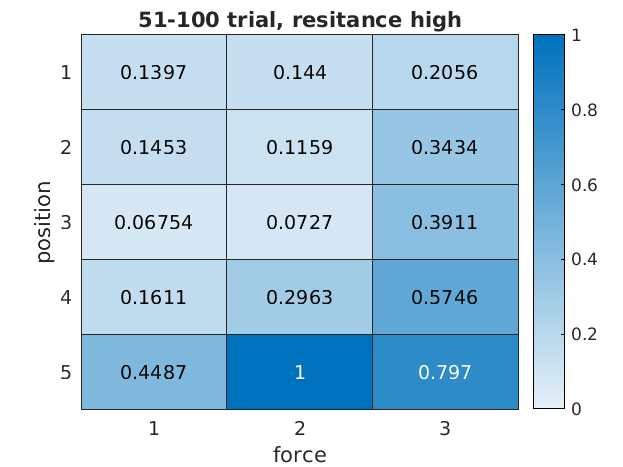


action_value_average_reshape4 = squeeze(action_value_average(2,6:10,:));
heatmap(action_value_average_reshape4,'ColorLimits',[0 1],'Title','51-100 trial, resitance high','XLabel','force','YLabel','position')
% heatmap(action_value_average_reshape4,'ColorLimits',[0 1],'Title','Second half trial, resitance high','XLabel','force','YLabel','position')
filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_Action_Value_51-100_high.png'];
saveas(gcf,filename);

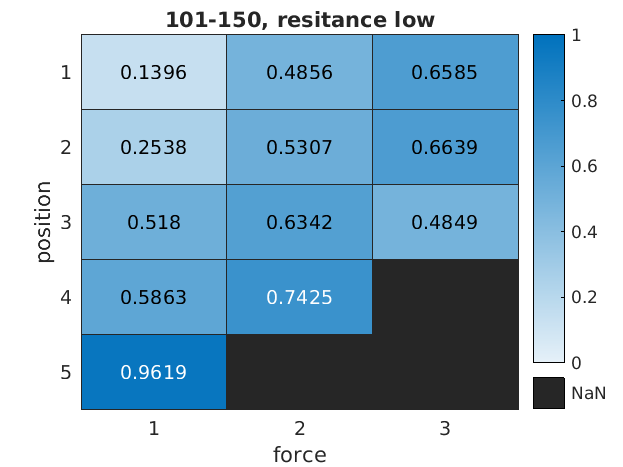


action_value_average_reshape5 = squeeze(action_value_average(3,1:5,:));
heatmap(action_value_average_reshape5,'ColorLimits',[0 1],'Title','101-150, resitance low','XLabel','force','YLabel','position')
% heatmap(action_value_average_reshape3,'ColorLimits',[0 1],'Title','Second half trial, resitance low','XLabel','force','YLabel','position')
filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_Action_Value_101-150_low.png'];
saveas(gcf,filename);

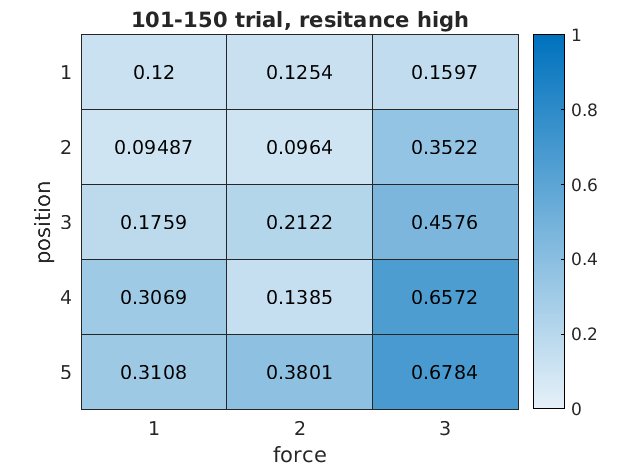


action_value_average_reshape6 = squeeze(action_value_average(3,6:10,:));
heatmap(action_value_average_reshape6,'ColorLimits',[0 1],'Title','101-150 trial, resitance high','XLabel','force','YLabel','position')
% heatmap(action_value_average_reshape4,'ColorLimits',[0 1],'Title','Second half trial, resitance high','XLabel','force','YLabel','position')
filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_Action_Value_101-150_high.png'];
saveas(gcf,filename);

% analyze by linearly increase the contribution of past trials
effective_trials = 50; % maximam trial which affect current state or action value
% calculate state value for each discretized state
% 2 (resistance) * 5 (position) = 10 states % 2 (resistance) * 6 (position) = 12 states
trial_num = length(data);
state_value = cell(length(Animal),trial_num,10);
for j_animal = 1:length(Animal)
    for i_trial = 1:trial_num
         % resistance for each trial
        if behavior_sequence_discretized{j_animal,i_trial}(1,2) == 8
            resistance_trial = 1;
        else 
            resistance_trial = 2;
        end
        % rewarded step (end of trial) or not (0)
        if max(behavior_sequence_discretized{j_animal,i_trial}(:,5)) == 1
            rewarded_trial = size(behavior_sequence_discretized{j_animal,i_trial},1);
        else 
            rewarded_trial = 0;
        end
        % calculate state_value of each step
        for j_step = 1:size(behavior_sequence_discretized{j_animal,i_trial},1)
            state_temp = (resistance_trial-1)*5+behavior_sequence_discretized{j_animal,i_trial}(j_step,7);
            if rewarded_trial >= 1
                state_value_temp = gamma.^(rewarded_trial-j_step);
            else
                state_value_temp = 0;
            end
            state_value{j_animal,i_trial,state_temp} = [state_value{j_animal,i_trial,state_temp} state_value_temp];
        end   
    end
end

state_value_average = zeros(length(Animal),trial_num,10);
for j_animal = 1:length(Animal)
    for i_trial = 1:trial_num
        for i = 1:10
            state_value_average(j_animal,i_trial,i) = mean(state_value{j_animal,i_trial,i});
    %     state_value_average(2,i) = mean(state_value{2,i});
        end
    end
end
% rewarded after how many steps or not

temp_state_value_average = state_value_average;

% save state value sequence
state_value_weighted_averages = zeros(length(Animal),trial_num,10);
for j_animal = 1:length(Animal)
    for i_trial = 1:trial_num
        for i = 1:10
            if i_trial > (effective_trials-1)
                nan_idx = ~isnan(temp_state_value_average(j_animal,i_trial-(effective_trials-1):i_trial,i));
                if sum(nan_idx) == 0
                    continue;
                else
                    state_value_weighted_averages(j_animal,i_trial,i) = squeeze(nansum(temp_state_value_average(j_animal,i_trial-(effective_trials-1):i_trial,i).*(1:effective_trials))/sum(nan_idx.*(1:effective_trials)));
                end
            else
                nan_idx = ~isnan(temp_state_value_average(j_animal,1:i_trial,i));
                if sum(nan_idx) == 0
                    continue;
                else               
                    state_value_weighted_averages(j_animal,i_trial,i) = squeeze(nansum(temp_state_value_average(j_animal,1:i_trial,i).*(1:i_trial))/sum(nan_idx.*(1:i_trial)));
                end
            end
        end
    end
    StateValue = squeeze(state_value_weighted_averages(j_animal,:,:));
    save([strjoin(data_folders(j_animal)) filesep strjoin(Animal(j_animal)) '_behavior_' strjoin(Date(j_animal)) '_' strjoin(Key(j_animal)) '.mat'], 'StateValue', '-append');
%     filename = [output_dir Date{j_animal} '_' Animal{j_animal} '_state_value.csv'];
%     writematrix(squeeze(state_value_weighted_averages(j_animal,:,:)),filename);
end

state_value_weighted_average = state_value_weighted_averages;

% state_value_weighted_average = zeros(length(Animal),trial_num,10);
% for j_animal = 1:length(Animal)
%     for j_trial = 1:trial_num
%         for i = 1:10
%             sum_weights = 0;
%             for i_trial = 1:effective_trials
%                 if j_trial-effective_trials+i_trial < 1
%                     continue
%                 end
%                 if ~isnan(state_value_average(j_animal,j_trial-effective_trials+i_trial,i))
%                     state_value_weighted_average(j_animal,j_trial,i) = state_value_weighted_average(j_animal,j_trial,i) + i_trial*state_value_average(j_animal,j_trial-effective_trials+i_trial,i);
%                     sum_weights = sum_weights + i_trial;
%                 end
%             end
%             state_value_weighted_average(j_animal,j_trial,i) = state_value_weighted_average(j_animal,j_trial,i)/sum_weights;
%         end
%     end
% end

% % calculate action value for each discretized state and action
% action_value = cell(length(Animal),trial_num,10,8);
% for j_animal = 1:length(Animal)
%     for i_trial = 1:trial_num
%          % resistance for each trial
%         if behavior_sequence_discretized{j_animal,i_trial}(1,2) == 8
%             resistance_trial = 1;
%         else 
%             resistance_trial = 2;
%         end
%         % rewarded step (end of trial) or not (0)
%         if max(behavior_sequence_discretized{j_animal,i_trial}(:,5)) == 1
%             rewarded_trial = size(behavior_sequence_discretized{j_animal,i_trial},1);
%         else 
%             rewarded_trial = 0;
%         end
%         % add state_value of each step
%         for j_step = 1:size(behavior_sequence_discretized{j_animal,i_trial},1)-1
%             state_temp = (resistance_trial-1)*5+behavior_sequence_discretized{j_animal,i_trial}(j_step,7);
%             state_temp_forward = (resistance_trial-1)*5+behavior_sequence_discretized{j_animal,i_trial}(j_step+1,7);
%             action_temp = behavior_sequence_discretized{j_animal,i_trial}(j_step,8)+1;
%             state_value_average_temp = state_value_weighted_average(j_animal,i_trial,state_temp_forward);
%             if rewarded_trial == j_step+1
%                 action_value_temp = 1; % + gamma*state_value_average_temp;
%             else
%                 action_value_temp = gamma*state_value_average_temp;
%             end
%             action_value{j_animal,i_trial,state_temp,action_temp} = [action_value{j_animal,i_trial,state_temp,action_temp} action_value_temp];
%         end
%     end
% end
% 
% 
% % action_value_average = zeros(trial_num,10,8);
% % for i_trial = 1:trial_num
% %     for i = 1:10
% %         for j = 1:8
% %             action_value_average(i_trial,i,j) = mean(action_value{i_trial,i,j});
% %         end
% %     end
% % end
% 
% temp_action_value_average = zeros(length(Animal),trial_num,10,8);
% for j_animal = 1:length(Animal)
%     for i_trial = 1:trial_num
%         for i = 1:10
%             for j = 1:8
%                 temp_action_value_average(j_animal,i_trial,i,j) = mean(action_value{j_animal,i_trial,i,j});      
%             end
%         end
%     end
% end
% action_value_average = squeeze(nanmean(temp_action_value_average,1));

% % plot action value at trial50 
% clf('reset')
% action_value_weighted_average = zeros(10,8);
% for i = 1:10
%     for j = 1:8
%         sum_weights = 0;
%         for i_trial = 1:effective_trials
%             if ~isnan(action_value_average(50-effective_trials+i_trial,i,j))
%                 action_value_weighted_average(i,j) = action_value_weighted_average(i,j) + i_trial*action_value_average(50-effective_trials+i_trial,i,j);
%                 sum_weights = sum_weights + i_trial;
%             end
%         end
%         action_value_weighted_average(i,j) = action_value_weighted_average(i,j)/sum_weights;
%     end    
% end
% 
% % state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);
% 
% action_value_weighted_average_reshape1 = action_value_weighted_average(1:5,:);
% heatmap(action_value_weighted_average_reshape1,'ColorLimits',[0 1],'Title','Action Value at 50 trial, resitance low','XLabel','force','YLabel','position')
% 
% action_value_weighted_average_reshape2 = action_value_weighted_average(6:10,:);
% heatmap(action_value_weighted_average_reshape2,'ColorLimits',[0 1],'Title','Action Value at 50 trial, resitance high','XLabel','force','YLabel','position')

% % plot action value at trial100 
% clf('reset')
% action_value_weighted_average = zeros(10,8);
% for i = 1:10
%     for j = 1:8
%         sum_weights = 0;
%         for i_trial = 1:effective_trials
%             if ~isnan(action_value_average(100-effective_trials+i_trial,i,j))
%                 action_value_weighted_average(i,j) = action_value_weighted_average(i,j) + i_trial*action_value_average(100-effective_trials+i_trial,i,j);
%                 sum_weights = sum_weights + i_trial;
%             end
%         end
%         action_value_weighted_average(i,j) = action_value_weighted_average(i,j)/sum_weights;
%     end    
% end
% 
% % state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);
% 
% action_value_weighted_average_reshape3 = action_value_weighted_average(1:5,:);
% heatmap(action_value_weighted_average_reshape3,'ColorLimits',[0 1],'Title','Action Value at 100 trial, resitance low','XLabel','force','YLabel','position')
% 
% action_value_weighted_average_reshape4 = action_value_weighted_average(6:10,:);
% heatmap(action_value_weighted_average_reshape4,'ColorLimits',[0 1],'Title','Action Value at 100 trial, resitance high','XLabel','force','YLabel','position')

% % plot action value at trial150 
% clf('reset')
% action_value_weighted_average = zeros(10,8);
% for i = 1:10
%     for j = 1:8
%         sum_weights = 0;
%         for i_trial = 1:effective_trials
%             if ~isnan(action_value_average(150-effective_trials+i_trial,i,j))
%                 action_value_weighted_average(i,j) = action_value_weighted_average(i,j) + i_trial*action_value_average(150-effective_trials+i_trial,i,j);
%                 sum_weights = sum_weights + i_trial;
%             end
%         end
%         action_value_weighted_average(i,j) = action_value_weighted_average(i,j)/sum_weights;
%     end    
% end
% 
% % state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);
% 
% action_value_weighted_average_reshape1 = action_value_weighted_average(1:5,:);
% heatmap(action_value_weighted_average_reshape1,'ColorLimits',[0 1],'Title','Action Value at 150 trial, resitance low','XLabel','force','YLabel','position')
% 
% action_value_weighted_average_reshape2 = action_value_weighted_average(6:10,:);
% heatmap(action_value_weighted_average_reshape2,'ColorLimits',[0 1],'Title','Action Value at 150 trial, resitance high','XLabel','force','YLabel','position')

% 

% % discretize force into just 3
% % analyze by linearly increase the contribution of past trials
% effective_trials = 50; % maximam trial which affect current state or action value
% % calculate state value for each discretized state
% % 2 (resistance) * 5 (position) = 10 states % 2 (resistance) * 6 (position) = 12 states
% trial_num = length(data);
% state_value = cell(length(Animal),trial_num,10);
% for j_animal = 1:length(Animal)
%     for i_trial = 1:trial_num
%          % resistance for each trial
%         if behavior_sequence_discretized{j_animal,i_trial}(1,2) == 8
%             resistance_trial = 1;
%         else 
%             resistance_trial = 2;
%         end
%         % rewarded step (end of trial) or not (0)
%         if max(behavior_sequence_discretized{j_animal,i_trial}(:,5)) == 1
%             rewarded_trial = size(behavior_sequence_discretized{j_animal,i_trial},1);
%         else 
%             rewarded_trial = 0;
%         end
%         % calculate state_value of each step
%         for j_step = 1:size(behavior_sequence_discretized{j_animal,i_trial},1)
%             state_temp = (resistance_trial-1)*5+behavior_sequence_discretized{j_animal,i_trial}(j_step,7);
%             if rewarded_trial >= 1
%                 state_value_temp = gamma.^(rewarded_trial-j_step);
%             else
%                 state_value_temp = 0;
%             end
%             state_value{j_animal,i_trial,state_temp} = [state_value{j_animal,i_trial,state_temp} state_value_temp];
%         end   
%     end
% end
% 
% % state_value_average = zeros(trial_num,10);
% % for i_trial = 1:trial_num
% %     for i = 1:10
% %         state_value_average(i_trial,i) = mean(state_value{i_trial,i});
% % %     state_value_average(2,i) = mean(state_value{2,i});
% %     end
% % end
% % rewarded after how many steps or not
% 
% state_value_average = zeros(length(Animal),trial_num,10);
% for j_animal = 1:length(Animal)
%     for i_trial = 1:trial_num
%         for i = 1:10
%             state_value_average(j_animal,i_trial,i) = mean(state_value{j_animal,i_trial,i});
%     %     state_value_average(2,i) = mean(state_value{2,i});
%         end
%     end
% end

% state_value_weighted_average = zeros(length(Animal),trial_num,10);
% for j_animal = 1:length(Animal)
%     for j_trial = 1:trial_num
%         for i = 1:10
%             sum_weights = 0;
%             for i_trial = 1:effective_trials
%                 if j_trial-effective_trials+i_trial < 1
%                     continue
%                 end
%                 if ~isnan(state_value_average(j_animal,j_trial-effective_trials+i_trial,i))
%                     state_value_weighted_average(j_animal,j_trial,i) = state_value_weighted_average(j_animal,j_trial,i) + i_trial*state_value_average(j_animal,j_trial-effective_trials+i_trial,i);
%                     sum_weights = sum_weights + i_trial;
%                 end
%             end
%             state_value_weighted_average(j_animal,j_trial,i) = state_value_weighted_average(j_animal,j_trial,i)/sum_weights;
%         end
%     end
% end

% calculate action value for each discretized state and action
action_value = cell(length(Animal),trial_num,10,3);
for j_animal = 1:length(Animal)
    for i_trial = 1:trial_num
         % resistance for each trial
        if behavior_sequence_discretized{j_animal,i_trial}(1,2) == 8
            resistance_trial = 1;
        else 
            resistance_trial = 2;
        end
        % rewarded step (end of trial) or not (0)
        if max(behavior_sequence_discretized{j_animal,i_trial}(:,5)) == 1
            rewarded_trial = size(behavior_sequence_discretized{j_animal,i_trial},1);
        else 
            rewarded_trial = 0;
        end
        % add state_value of each step
        for j_step = 1:size(behavior_sequence_discretized{j_animal,i_trial},1)-1
            state_temp = (resistance_trial-1)*5+behavior_sequence_discretized{j_animal,i_trial}(j_step,7);
            state_temp_forward = (resistance_trial-1)*5+behavior_sequence_discretized{j_animal,i_trial}(j_step+1,7);
            action_temp = min(behavior_sequence_discretized{j_animal,i_trial}(j_step,8)+1, 3); % clip force upto 3
            state_value_average_temp = state_value_weighted_average(j_animal,i_trial,state_temp_forward);
            if rewarded_trial == j_step+1
                action_value_temp = 1; % + gamma*state_value_average_temp;
            else
                action_value_temp = gamma*state_value_average_temp;
            end
            action_value{j_animal,i_trial,state_temp,action_temp} = [action_value{j_animal,i_trial,state_temp,action_temp} action_value_temp];
        end
    end
end

% action_value_average = zeros(trial_num,10,3);
% for i_trial = 1:trial_num
%     for i = 1:10
%         for j = 1:3
%             action_value_average(i_trial,i,j) = mean(action_value{i_trial,i,j});
%         end
%     end
% end

temp_action_value_average = zeros(length(Animal),trial_num,10,3);
for j_animal = 1:length(Animal)
    for i_trial = 1:trial_num
        for i = 1:10
            for j = 1:3
                temp_action_value_average(j_animal,i_trial,i,j) = mean(action_value{j_animal,i_trial,i,j});      
            end
        end
    end
end
action_value_average = squeeze(nanmean(temp_action_value_average,1));

% save action value sequence
action_value_weighted_averages = zeros(length(Animal),trial_num,10,3);
for j_animal = 1:length(Animal)
    for i_trial = 1:trial_num
        for i = 1:10
            for j = 1:3
                if i_trial > (effective_trials-1)
                    nan_idx = ~isnan(temp_action_value_average(j_animal,i_trial-(effective_trials-1):i_trial,i,j));
                    if sum(nan_idx) == 0
                        continue;
                    else
                        action_value_weighted_averages(j_animal,i_trial,i,j) = squeeze(nansum(temp_action_value_average(j_animal,i_trial-(effective_trials-1):i_trial,i,j).*(1:effective_trials))/sum(nan_idx.*(1:effective_trials))); %(j-1)*10+i
                    end
                else
                    nan_idx = ~isnan(temp_action_value_average(j_animal,1:i_trial,i,j));
                    if sum(nan_idx) == 0
                        continue;
                    else               
                        action_value_weighted_averages(j_animal,i_trial,i,j) = squeeze(nansum(temp_action_value_average(j_animal,1:i_trial,i,j).*(1:i_trial))/sum(nan_idx.*(1:i_trial)));
                    end
                end
            end
        end
    end
    ActionValue = squeeze(action_value_weighted_averages(j_animal,:,:,:));
    save([strjoin(data_folders(j_animal)) filesep strjoin(Animal(j_animal)) '_behavior_' strjoin(Date(j_animal)) '_' strjoin(Key(j_animal)) '.mat'], 'ActionValue', '-append');
%     filename = [output_dir Date{j_animal} '_' Animal{j_animal} '_state_value.csv'];
%     writematrix(squeeze(state_value_weighted_averages(j_animal,:,:)),filename);
end

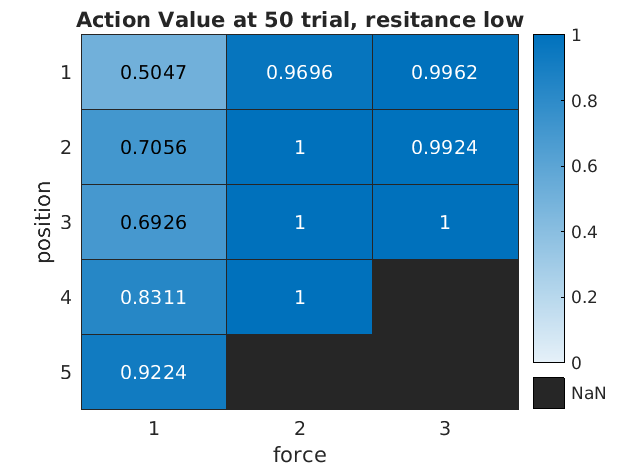

% plot action value at trial50 
clf('reset')
action_value_weighted_average = zeros(10,3);
for i = 1:10
    for j = 1:3
        sum_weights = 0;
        for i_trial = 1:effective_trials
            if ~isnan(action_value_average(50-effective_trials+i_trial,i,j))
                action_value_weighted_average(i,j) = action_value_weighted_average(i,j) + i_trial*action_value_average(50-effective_trials+i_trial,i,j);
                sum_weights = sum_weights + i_trial;
            end
        end
        action_value_weighted_average(i,j) = action_value_weighted_average(i,j)/sum_weights;
    end    
end

% state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);

action_value_weighted_average_reshape1 = action_value_weighted_average(1:5,:);
heatmap(action_value_weighted_average_reshape1,'ColorLimits',[0 1],'Title','Action Value at 50 trial, resitance low','XLabel','force','YLabel','position')

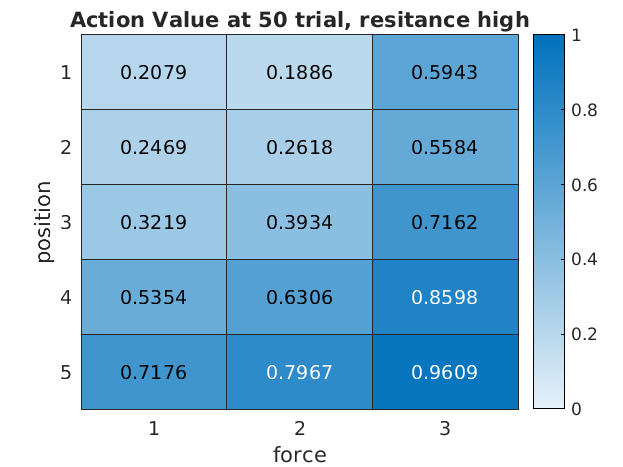

filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_Action_Value_at50_low.png'];
% saveas(gcf,filename);
action_value_weighted_average_reshape2 = action_value_weighted_average(6:10,:);
heatmap(action_value_weighted_average_reshape2,'ColorLimits',[0 1],'Title','Action Value at 50 trial, resitance high','XLabel','force','YLabel','position')

filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_Action_Value_at50_high.png'];
% saveas(gcf,filename);

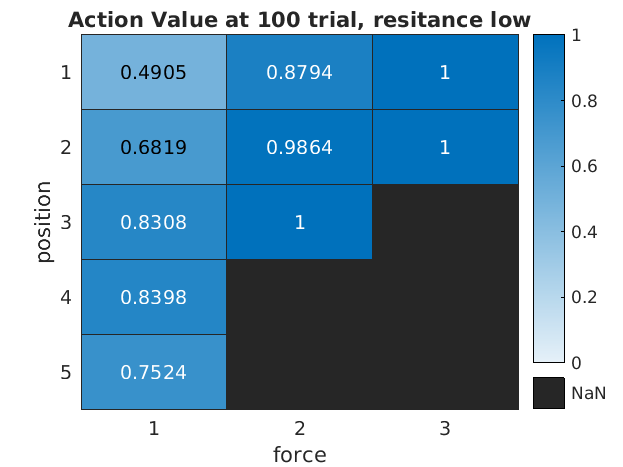

% plot action value at trial100 
clf('reset')
action_value_weighted_average = zeros(10,3);
for i = 1:10
    for j = 1:3
        sum_weights = 0;
        for i_trial = 1:effective_trials
            if ~isnan(action_value_average(100-effective_trials+i_trial,i,j))
                action_value_weighted_average(i,j) = action_value_weighted_average(i,j) + i_trial*action_value_average(100-effective_trials+i_trial,i,j);
                sum_weights = sum_weights + i_trial;
            end
        end
        action_value_weighted_average(i,j) = action_value_weighted_average(i,j)/sum_weights;
    end    
end

% state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);

action_value_weighted_average_reshape3 = action_value_weighted_average(1:5,:);
heatmap(action_value_weighted_average_reshape3,'ColorLimits',[0 1],'Title','Action Value at 100 trial, resitance low','XLabel','force','YLabel','position')

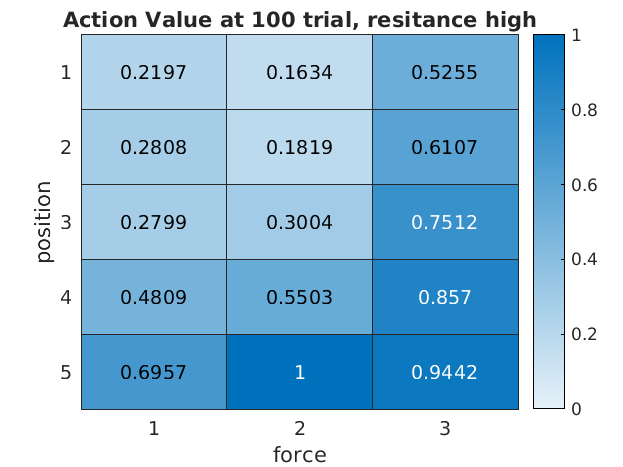

filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_Action_Value_at100_low.png'];
% saveas(gcf,filename);
action_value_weighted_average_reshape4 = action_value_weighted_average(6:10,:);
heatmap(action_value_weighted_average_reshape4,'ColorLimits',[0 1],'Title','Action Value at 100 trial, resitance high','XLabel','force','YLabel','position')

filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_Action_Value_at100_high.png'];
% saveas(gcf,filename);

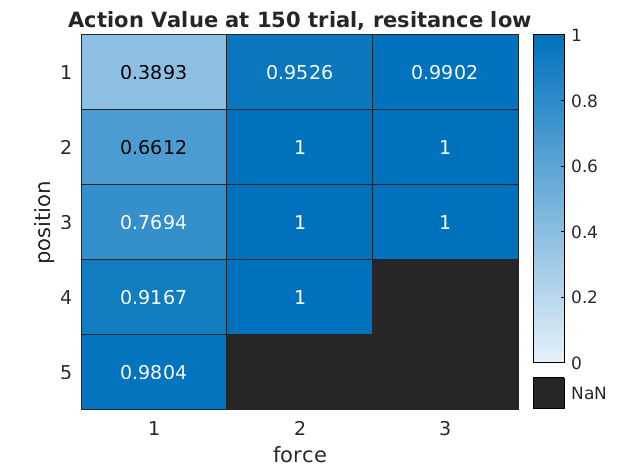

% plot action value at trial150 
clf('reset')
action_value_weighted_average = zeros(10,3);
for i = 1:10
    for j = 1:3
        sum_weights = 0;
        for i_trial = 1:effective_trials
            if ~isnan(action_value_average(150-effective_trials+i_trial,i,j))
                action_value_weighted_average(i,j) = action_value_weighted_average(i,j) + i_trial*action_value_average(150-effective_trials+i_trial,i,j);
                sum_weights = sum_weights + i_trial;
            end
        end
        action_value_weighted_average(i,j) = action_value_weighted_average(i,j)/sum_weights;
    end    
end

% state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);

action_value_weighted_average_reshape1 = action_value_weighted_average(1:5,:);
heatmap(action_value_weighted_average_reshape1,'ColorLimits',[0 1],'Title','Action Value at 150 trial, resitance low','XLabel','force','YLabel','position')

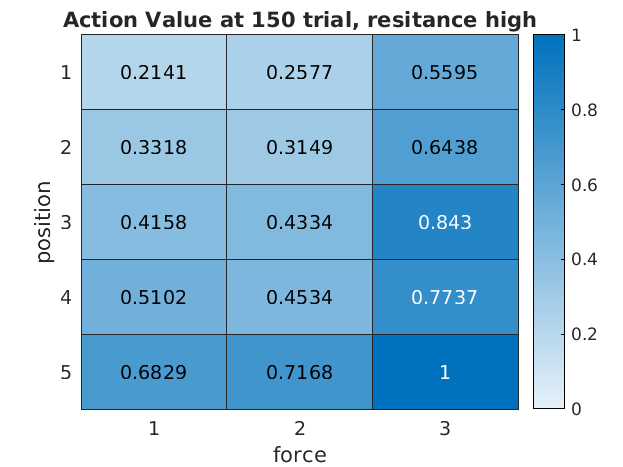

filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_Action_Value_at150_low.png'];
% saveas(gcf,filename);
action_value_weighted_average_reshape2 = action_value_weighted_average(6:10,:);
heatmap(action_value_weighted_average_reshape2,'ColorLimits',[0 1],'Title','Action Value at 150 trial, resitance high','XLabel','force','YLabel','position')

filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_Action_Value_at150_high.png'];
% saveas(gcf,filename);

% analyze by binned 20 trials
behavior_adapt = cell(6,20);
for i = 1:6
    if i == 6
        behavior_adapt(6,:) = behavior_sequence_discretized(length(data)-19:length(data));
    else
        behavior_adapt(i,:) = behavior_sequence_discretized((i-1)*20+1:i*20);
    end
end
% behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
% behavior_adapt(2,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-49:length(behavior_sequence_processed)); % behavior_after_adapt

% calculate state value for each discretized state
% 2 (resistance) * 6 (position) = 12 states
state_value = cell(6,12);
for k = 1:6
    for i_trial = 1:20
        % resistance for each trial
        if behavior_adapt{k,i_trial}(1,2) == 8
            resistance_trial = 1;
        else 
            resistance_trial = 2;
        end
        % rewarded step (end of trial) or not (0)
        if max(behavior_adapt{k,i_trial}(:,5)) == 1
            rewarded_trial = length(behavior_adapt{k,i_trial});
        else 
            rewarded_trial = 0;
        end
        % add state_value of each step
        for j_step = 1:length(behavior_adapt{k,i_trial})
            state_temp = (resistance_trial-1)*6+behavior_adapt{k,i_trial}(j_step,7);
            if rewarded_trial >= 1
                state_value_temp = gamma.^(rewarded_trial-j_step);
            else
                state_value_temp = 0;
            end
            state_value{k,state_temp} = [state_value{k,state_temp} state_value_temp];
        end
    end
end

Index in position 1 exceeds array bounds. Index must not exceed 2.


state_value_average = zeros(6,12);
for k = 1:6
    for i = 1:12
        state_value_average(k,i) = mean(state_value{k,i});
%     state_value_average(2,i) = mean(state_value{2,i});
    end
end
% rewarded after how many steps or not

% plot state value
addpath(['C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\PCA_and_ICA\Subaxis']);
for i = 1:6
% state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
% heatmap(state_value_average_reshape)
    subaxis(2,3,i, 'Spacing', 0.02, 'Padding', 0.02, 'Margin', 0.03);
%     clims = [-3 10]; % use clims specified by the previous cell
%     image = mean(mean_RecICA_Temp(:,time_points(i,1)*fps/1000:time_points(i,2)*fps/1000),2);
    state_value_average_reshape = reshape(state_value_average(i,:),[6,2]); %mean(mean_RecICA_lift(:,timepoints(i,1):timepoints(i,2)),2);
    imagesc(state_value_average_reshape,[0 1]);
    colormap jet;
    axis square;
%     axis off;
    title(['Trial ' num2str(1+(i-1)*20) '-' num2str(i*20)], 'FontSize',8);
    xlabel('resistance');
    ylabel('position');

end

gamma = 0.99 % discount factor
x = 1:100;
y = gamma.^x;
plot(y)

steps = 0;
for i_trial = 1:length(data)
    steps = steps + length(data{i_trial});
end
steps = steps/length(data)

max_forces = zeros(1,length(data));
for i = 1:length(data)
    max_forces(i) = max(data{i}(:,4));
end
histogram(max_forces)